# Social LEAP Estimates Animal Poses (SLEAP) using MATLAB

[**SLEAP**](http://sleap.ai) is an open source deep-learning based framework for estimating positions of animal body parts. This demo shows how to import SLEAP models trained using TensorFlow 2 into MATLAB and run inference on videos. 

The example uses two deep learning models: Centroid and Top-down model. The centroid model provides confidence heatmaps for presence of animal(s) in a frame. Animals are then cropped and sent individually to topdown model that is then used to estimate keypoints or positions of the animal.

## Setup Paths 

videoPath = fullfile(pwd, "sample_data", "test_clip.mp4");
centroidModelPath = fullfile(pwd, "pretrained_models", 'centroids.200823_193403.UNet');
topdownModelPath = fullfile(pwd, "pretrained_models", 'topdown.200823_204048.UNet');

## Initialize model configurations

% Load models and configs.
centroidConfig = helper.loadJobConfig(centroidModelPath);
inputScale = centroidConfig.data.preprocessing.input_scaling;

topdownConfig = helper.loadJobConfig(topdownModelPath);
bboxSize = [topdownConfig.data.instance_cropping.crop_size topdownConfig.data.instance_cropping.crop_size];

minThreshold = 0.3; % minimum threshold to be considered for instance cropping from centroid model output

centroidModel = helper.loadModel(centroidModelPath);

topdownModel = helper.loadModel(topdownModelPath);

## Form a single model

To improve efficiency of prediction, both centroid and top-down models are combined to form a single DAG network object. The post-processing in between the models and after the models are written as custom layers and combined within the same DAG network object.

net = TopDownModel.formDAGNetwork(centroidModel, topdownModel, inputScale, bboxSize, minThreshold, centroidConfig, topdownConfig);

## Real-time prediction on video frames

This section reads one frame after another from the video and runs prediction on the frame. The prediction keypoints are visualized on the animals.

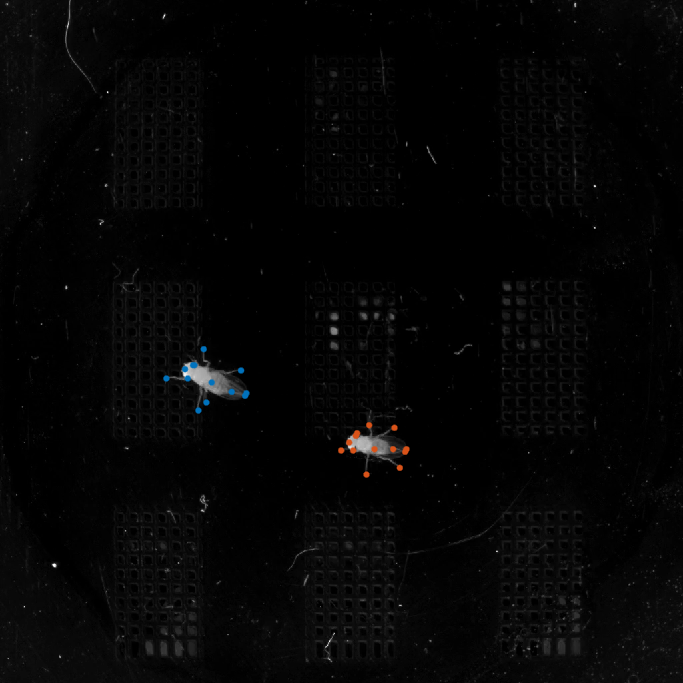

vr = VideoReader(videoPath);
vds1 = helper.makeVideoDatastore(videoPath);
vds = transform(vds1, @(x) preprocessImage(x, inputScale));

f1 = figure("Visible","on");
f1.Name = "Real-time prediction on video";

while hasFrame(vr)
    thisImg = read(vds);
    thisImgPeaks = net.predict(thisImg);
    helper.vizPeaks(vr.readFrame, squeeze(thisImgPeaks))
    pause(1/vr.FrameRate);
end

## Run inference on entire video

This section shows how to run prediction on the entire video at once.

vds1 = helper.makeVideoDatastore(videoPath);
vds = transform(vds1, @(x) preprocessImage(x, inputScale));
[Y, numAnimalsPerFrame] = net.predict(vds, 'MiniBatchSize', 16);
Y = squeeze(Y);

% Visualize
f2 = figure("Visible","on");
f2.Name = "Visualize predicted results";

vr = VideoReader(videoPath);
animalCnts = [0; cumsum(numAnimalsPerFrame)];
for frameIdx = 1:vr.NumFrames
    thisImg = vr.read(frameIdx);
    thisImg = preprocessImage(thisImg);
    thisImgPeaks = Y(:,:,animalCnts(frameIdx)+1:animalCnts(frameIdx+1));
    helper.vizPeaks(thisImg, thisImgPeaks)
    title(string(frameIdx));
    pause(1/vr.FrameRate);
end

## Helper functions

function I = preprocessImage(I, inputScale)
if nargin < 2 || isempty(inputScale)
    inputScale = 1; %Default
end

I = rgb2gray(I);
I = single(I) / 255;
I = imresize(I, inputScale);
end